# Continuation of periodic orbits

We consider a four-node network of oscillators coupled through linear spring. The damping of the first node is of van der pol type and this node subjects to external harmonic forcing. The equation of motion of this system is given as follows


$$\ddot{u}_1+(\epsilon u_1^2-1)\dot{u}_1+3u_1-u_2-u_4=\epsilon a\cos\Omega t,\\
\ddot{u}_2+0.8\dot{u}_2-u_1+4u_2-u_3-u_4=0,\\
\ddot{u}_3+0.8\dot{u}_3-u_2+2u_3=0,\\
\ddot{u}_4+0.8\dot{u}_4-u_1-u_2+3u_4=0
$$


More details about this model can be found in [1]. In this demo, we will perform

- continuation of periodic orbits with varied $\Omega$ using 1st order formulation,

- continuation of periodic orbits with varied $\Omega$ using 2nd order formulation.

[1] Yu Mao and Harry Dankowicz. Topology-dependent Excitation Response of Networks of Linear and Nonlinear Oscillators

# First-order formulation

## Construct an of initial periodic orbit 

% pnames = [ om a ]
p0 = [ 2; 0.4 ];
T0 = 0;
T  = 2*pi/p0(1);
[~,x]  = ode45(@(t,x) net(t,x,p0), 0:1000*T, zeros(8,1)); % Approximate periodic orbit of reduced system
[t,x] = ode45(@(t,x) net(t,x,p0), linspace(0,T,200), x(end,:));

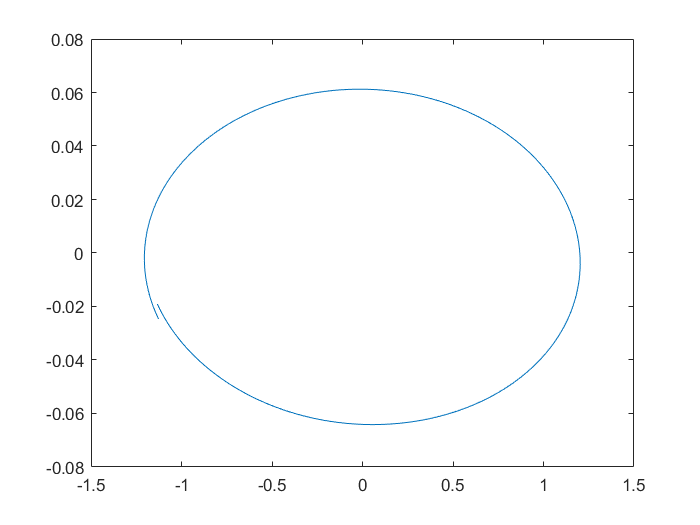

figure;
plot(x(:,1),x(:,2))


x0 = x(1,:);
x1 = x(5,:);

## Continuation of periodic orbit

prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'h_max', 5);
prob = coco_set(prob, 'forward', 'autonomous', false);
%% first run
forward_args = {@net, @net_DFDX, @net_DFDP, T0, T, x0, x1, {'omega' 'amp'}, p0};
prob1 = ode_isol2forward(prob, '',forward_args{:});

[data, uidx] = coco_get_func_data(prob1, 'forward', 'data', 'uidx');
bc_funcs = {@net_bc, @net_bc_du};
prob1 = coco_add_func(prob1, 'bc', bc_funcs{:}, [], 'zero', 'uidx', ...
  uidx([data.x0_idx, data.x1_idx, data.T0_idx, data.T_idx, data.p_idx(1)]));

% continuation
cont_pars = {'omega' 'amp'};
coco(prob1, 'net-first', [], 1, cont_pars, [1.95 2.05]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          5.57e-01  5.19e+00    0.0    0.0    0.0
   1   1  1.00e+00  3.97e-01  3.33e-03  5.05e+00    0.1    0.0    0.0
   2   1  1.00e+00  7.57e-03  7.91e-06  5.05e+00    0.1    0.1    0.0
   3   1  1.00e+00  3.21e-05  1.96e-09  5.05e+00    0.1    0.1    0.0
   4   1  1.00e+00  1.97e-09  1.89e-09  5.05e+00    0.1    0.1    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega          amp
    0  00:00:00   5.0473e+00      1  EP      2.0018e+00   4.0000e-01
   10  00:00:02   6.2726e+00      2          2.0004e+00   4.0000e-01
   20  00:00:04   6.4284e+00      3          1.9996e+00   4.0000e-01
   30  00:00:05   6.0277e+00      4          1.9987e+00   4.0000e-01
   40  00:00:07   4.6707e+00      5          1.9971e+00   4.0000e-01
   50  00:00:08   4.5091e+00      6          1.9962e+00   4.0000e-01
   60  00:00:10   4.4410e

# Second-order formulation

## Setup 2nd-order system

M = eye(4);
C = diag([-1; 0.8 ;0.8 ;0.8]);
K = [3 -1 0 -1;-1 4 -1 -1;0 -1 2 0;-1 -1 0 3];
ep = 0.05;
N  = @(u,v) ep*C*v+K*u+[ep*u(1)^2*v(1);0;0;0];
Nu = @(u,v) K+[2*ep*u(1)*v(1) 0  0 0; zeros(3,4)];
Nv = @(u,v) ep*C+[ep*u(1)^2 0 0 0; zeros(3,4)];
F  = @(t,p) [ep*p(2)*cos(p(1)*t);0;0;0];
Fp = @(t,p) [-ep*p(2)*t*sin(p(1)*t) ep*cos(p(1)*t);zeros(3,2)];

Forward simulation using Newmark

opts.RelTol = 1e-6;
opts.ItMX   = 10;
opts.Nsteps = 50000;
[uend,vend,~,~] = Newmark(M,N,Nu,Nv,F,Fp,T0,100*T,zeros(8,1),p0,opts);
x0 = [uend;vend];
opts.Nsteps = 500;
[uend,vend,~,~,ut] = Newmark(M,N,Nu,Nv,F,Fp,T0,T,x0,p0,opts,'out');
x1 = [uend;vend];

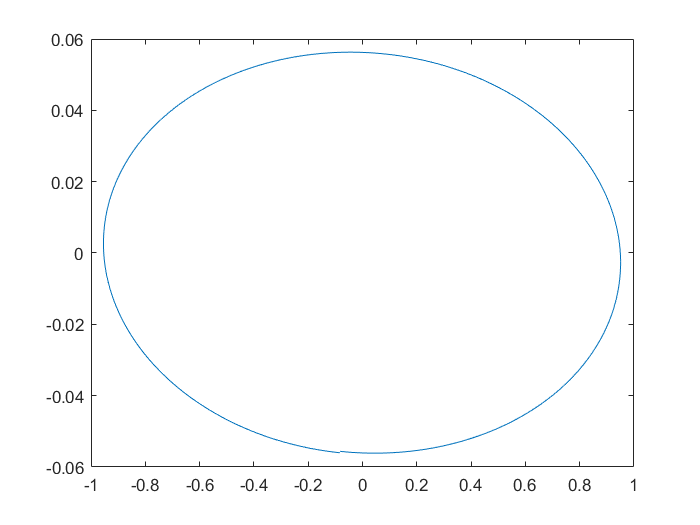

figure;
plot(ut(1,:),ut(2,:))

## Continuation of periodic orbit

prob = coco_prob();
prob = coco_set(prob, 'forward', 'autonomous', false, 'order', 2);
prob = coco_set(prob, 'cont', 'h_max', 5)

prob = struct with fields:
    opts: [1×1 coco_opts_tree]


ode_opts.RelTol  = 1e-8;
ode_opts.Nsteps  = 300;
prob = coco_set(prob,'forward','ode_opts',ode_opts,'ODEsolver',@Newmark);
%% first run
forward_args = {M, N, Nu, Nv, F, [], Fp, T0, T, x0, x1, {'omega' 'amp'}, p0};
prob1 = ode_isol2forward(prob, '',forward_args{:});

[data, uidx] = coco_get_func_data(prob1, 'forward', 'data', 'uidx');
bc_funcs = {@net_bc, @net_bc_du};
prob1 = coco_add_func(prob1, 'bc', bc_funcs{:}, [], 'zero', 'uidx', ...
  uidx([data.x0_idx, data.x1_idx, data.T0_idx, data.T_idx, data.p_idx(1)]));

% continuation
cont_pars = {'omega' 'amp'};
coco(prob1, 'net-second', [], 1, cont_pars, [1.95 2.05]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.96e-02  5.69e+00    0.0    0.0    0.0
   1   1  4.74e-01  1.44e+00  1.07e-02  6.16e+00    0.1    0.0    0.0
   2   1  1.00e+00  3.60e-01  1.01e-03  6.42e+00    0.1    0.1    0.0
   3   1  1.00e+00  3.41e-02  8.56e-06  6.39e+00    0.1    0.1    0.0
   4   1  1.00e+00  2.92e-04  6.09e-10  6.39e+00    0.1    0.1    0.0
   5   1  1.00e+00  2.01e-08  3.60e-13  6.39e+00    0.2    0.1    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega          amp
    0  00:00:00   6.3941e+00      1  EP      2.0000e+00   4.0000e-01
   10  00:00:02   6.3756e+00      2          1.9993e+00   4.0000e-01
   20  00:00:04   5.6769e+00      3          1.9982e+00   4.0000e-01
   30  00:00:06   4.5654e+00      4          1.9966e+00   4.0000e-01
   40  00:00:08   4.4905e+00      5          1.9959e+00   4.0000e-01
   50  00:00:09   4.4042

## Comparison of results

bd  = coco_bd_read('net-first');
lab = coco_bd_labs(bd, 'EP');
lab = max(lab);
sol1 = forward_read_solution('', 'net-first', lab)

sol1 = struct with fields:
    t0: []
    T0: 0
     T: 3.0650
    x0: [8×1 double]
    x1: [8×1 double]
     p: [2×1 double]



bd  = coco_bd_read('net-second');
lab = coco_bd_labs(bd, 'EP');
lab = max(lab);
sol2 = forward_read_solution('', 'net-second', lab)

sol2 = struct with fields:
    t0: []
    T0: 0
     T: 3.0650
    x0: [8×1 double]
    x1: [8×1 double]
     p: [2×1 double]



[sol1.x0 sol2.x0]

ans =    -0.0503   -0.0502
   -0.0073   -0.0073
    0.0034    0.0034
    0.0480    0.0480
   -0.0065   -0.0064
   -0.0086   -0.0086
    0.0036    0.0036
    0.0058    0.0058
